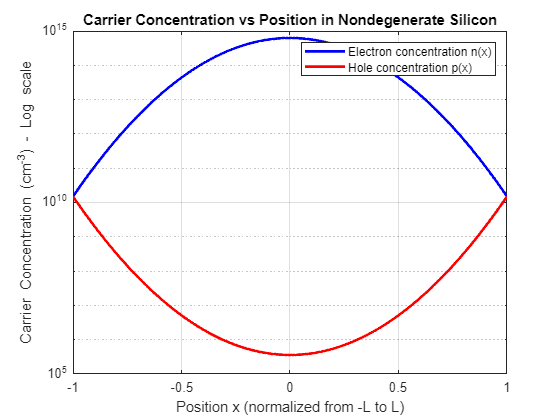

% Constants
Eg = 1.1;  % Bandgap of Silicon in eV
ni = 1.5e10;  % Intrinsic carrier concentration for Silicon at 300 K in cm^-3
k = 8.617e-5;  % Boltzmann constant in eV/K
T = 300;  % Temperature in K
L = 1;  % Normalized half-length of the semiconductor

% Position range
x = linspace(-L, L, 1000);

% Quadratic function for E_F - E_i, with the correct boundary conditions
A = Eg / (4 * L^2);
E_F_minus_E_i = A * (L^2 - x.^2);

% Calculate carrier concentrations using nondegenerate approximation
n = ni * exp((E_F_minus_E_i) / (k * T));
p = ni * exp((-E_F_minus_E_i) / (k * T));

% Plotting using a logarithmic scale for y-axis
figure;
semilogy(x, n, 'b', 'LineWidth', 2);
hold on;
semilogy(x, p, 'r', 'LineWidth', 2);
title('Carrier Concentration vs Position in Nondegenerate Silicon');
xlabel('Position x (normalized from -L to L)');
ylabel('Carrier Concentration (cm^{-3}) - Log scale');
legend('Electron concentration n(x)', 'Hole concentration p(x)');
grid on;